% Implementation of Phase Stretch Transform (PST) in Matlab
% Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA


%%Initial Setup 
clc  % clear screen
clear all  % clear all variables
close all   % close all figures
addpath('src/'); % script source directory

% New image loading
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');
centroids_over_time = [];

%for time_slice = 1:size(cell_dataset, 4)
    time_slice = 1;
    disp(time_slice);

     1



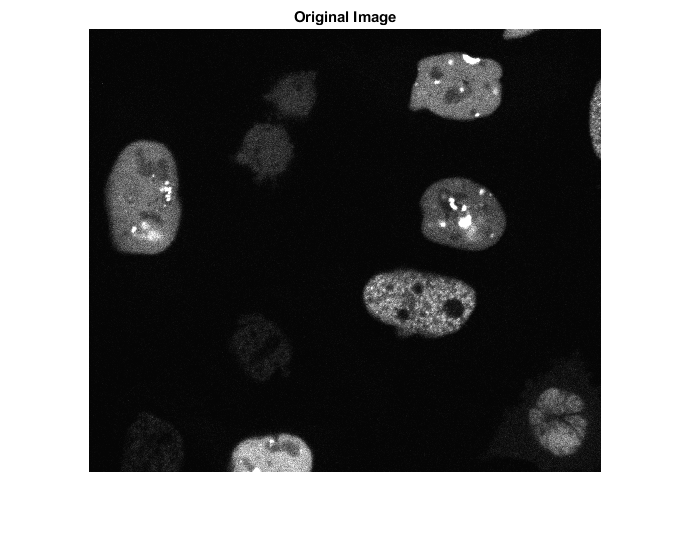

    % Work with a single 3D image for now
    Image_orig = cell_dataset(:,:,:, time_slice);
    
    % Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
    % Voxel size (microns): 0.202 x 0.202 x 1.0
    % Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
    % (good enough)
    Image_orig = repelem(Image_orig, 1, 1, 5);
    
    %show the original image
    %subplot(1,2,1)
    %Image_orig = im2double(Image_orig(:,:,:));
    imshow(Image_orig(:,:,1))
    title('Original Image') % convert the grayscale image do a 2D double array

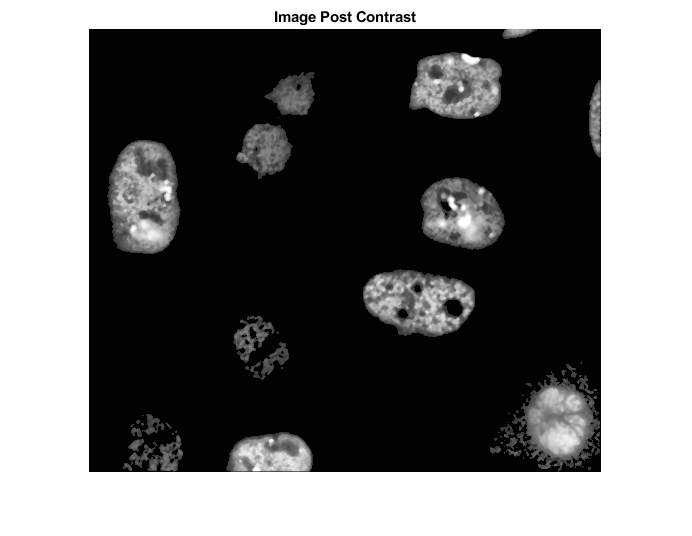

    
    %% Other edge detections
    % MK: Show edges using 1st order Sobel edge detector kernel
%     figure;
%     edge(Image_orig(:,:,6), 'sobel');
%     title('Original Image, Sobel edge detector');
%     figure;
%     edge(Image_orig(:,:,6), 'log');
%     title('Original Image, LoG edge detector');
%     figure;
    
    %% Noise Thresholding and Contrast
    %Thresholding and Clahe algo before pst contrast step to make cells more visible 
    for i = 1:size(Image_orig, 3)
        Image_orig(Image_orig<20)=2;
        %Image_orig = Image_orig * 1.05;
        %Image_orig(Image_orig<20)=2;
        
        Image_orig(:,:,i) = filter2(fspecial('average',2),Image_orig(:,:,i));
        
        Image_orig(:,:,i) = medfilt2(Image_orig(:,:,i));
        Image_orig(:,:,i) = adapthisteq(Image_orig(:,:,i), 'ClipLimit', 0.05);
        Image_orig(Image_orig<50)=2;
    end
    imshow(Image_orig(:,:,1))
    title('Image Post Contrast')

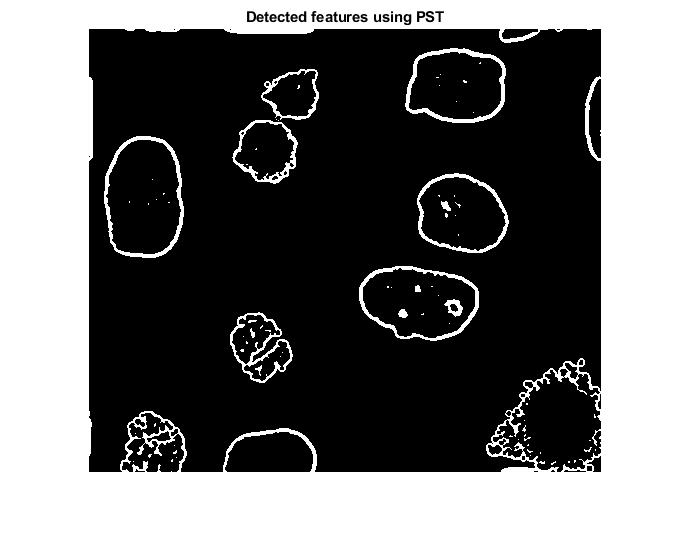

    
    %% PST
    % low-pass filtering (also called localization) parameter
    handles.LPF=0.20; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)
    
    % PST parameters
    handles.Phase_strength=5;  % PST  kernel Phase Strength
    handles.Warp_strength=12.48;  % PST Kernel Warp Strength
    
    % Thresholding parameters (for post processing)
    handles.Thresh_min=-1;  % minimum Threshold  (a number between 0 and -1)
    handles.Thresh_max= 0.0019;  % maximum Threshold  (a number between 0 and 1)
    handles.Thresh_dark = 1/9; % dark threshold (between 0 and 1)
    
    [features, PST_Kernel] = PST_ND(Image_orig, handles);
    [edge] = PST_post(Image_orig, features, handles);
    
    
    % MK: Best edges on Z layer 21
    refined_edge = edge(:,:,21:25);
    
    % Show and save 'analog' edge output
    filename = 't000.tif';
    figure;
    features_img = [];
    for i = 1:size(features, 3)
        features_img(:,:,i) = features(:,:,i)/max(features(:,:,i), [], 'all')*3;
    end
    %features_img = features(:,:,1)/max(features, [], 'all')*3;
    
    % Post proccess features_img
    %edge(edge < 0) = 0;
    features_img(features_img >0.005) = 1;

    imshow(features_img(:,:,1))
    title('Detected features using PST')

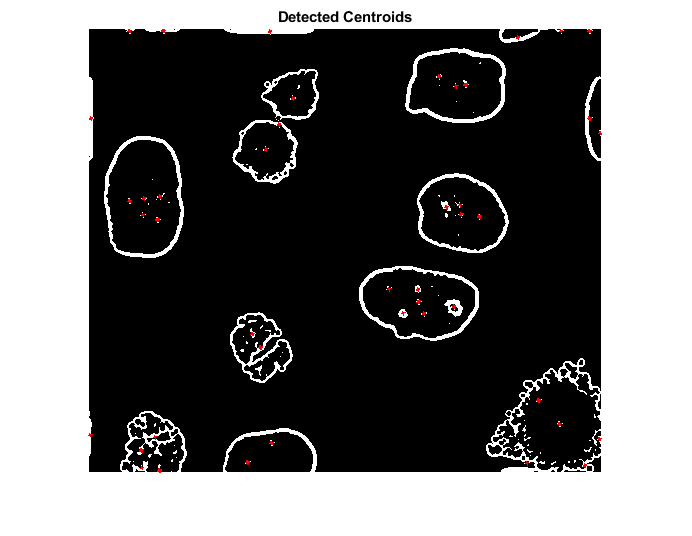

    file_and_extension = strsplit(filename,'.');
    output_path = char(strcat('data/Test_Images/',file_and_extension(1),'_features.tif'));
    imwrite(features_img(:,:,1), output_path);
    
    %%Centroid Detection via DoG
    
    %Convert image to binary blobs
    
    scale_space = dog2(features_img(:,:,1), [4, 9, 16, 25, 36, 49, 64]);
    scale_space(scale_space <0.05) = 0;
    scale_space(scale_space>0.05) = 1;
    
    %Centroid Detection
    cc = bwconncomp(scale_space(:,:,6), 26);
    stats = regionprops(cc, 'Centroid');
    start_cents = [];
    for i = 1:size(stats, 1)
        start_cents = [start_cents ; stats(i).Centroid];
    end
    
    %TODO: Wrap centroids in a data type so no need to deal with different
    %sized arrays (changes in number of centroids)
    
    %centroids_over_time(:,:, time_slice) = start_cents;
    
    % Show Centroids on PST
    figure;
    imshow(features_img(:,:,1));
    radii = ones(size(start_cents, 1), 1) * 1;
    viscircles(start_cents(:,[1,2]), radii);
    title('Detected Centroids')

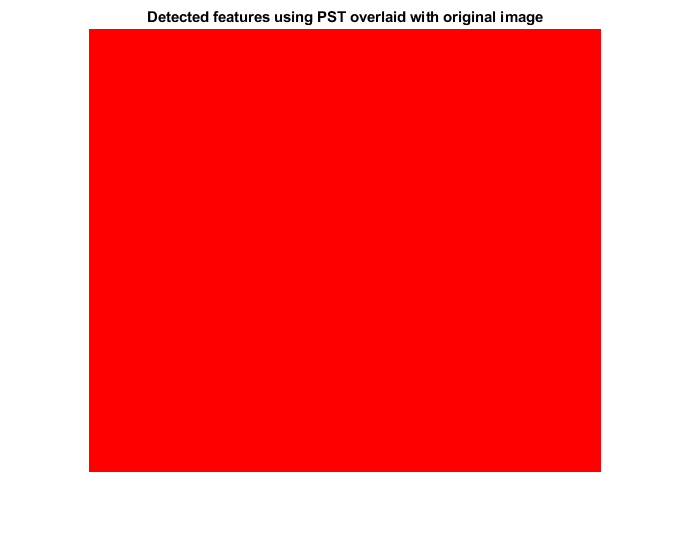

    % save the image
    file_and_extension=strsplit(filename,'.');
    output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_edge.tif'));
    imwrite(features_img(:,:,1), output_path);
    
    
    % overlay original image with detected features
    overlay = imoverlay(Image_orig, features_img(:,:,1), [1 0 0]);
    figure;
    %imshow(overlay/max(overlay, [], 'all'));
    imshow(overlay);
    title('Detected features using PST overlaid with original image')

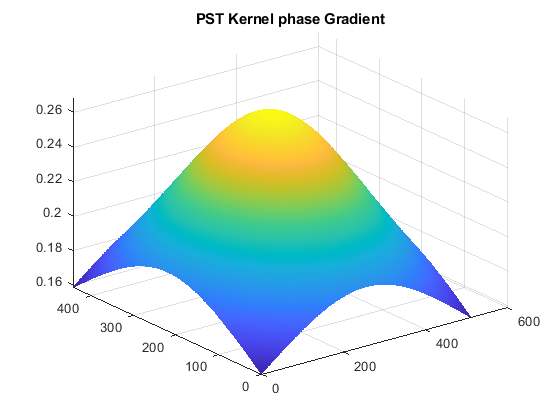

    % save the image
    output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_overlay.tif'));
    imwrite(overlay/max(overlay, [], 'all'), output_path);
    
    % show the PST phase kernel gradient
    figure;
    [D_PST_Kernel_x, D_PST_Kernel_y, D_PST_Kernel_z]=gradient(PST_Kernel);
    mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
    title('PST Kernel phase Gradient');


%end

